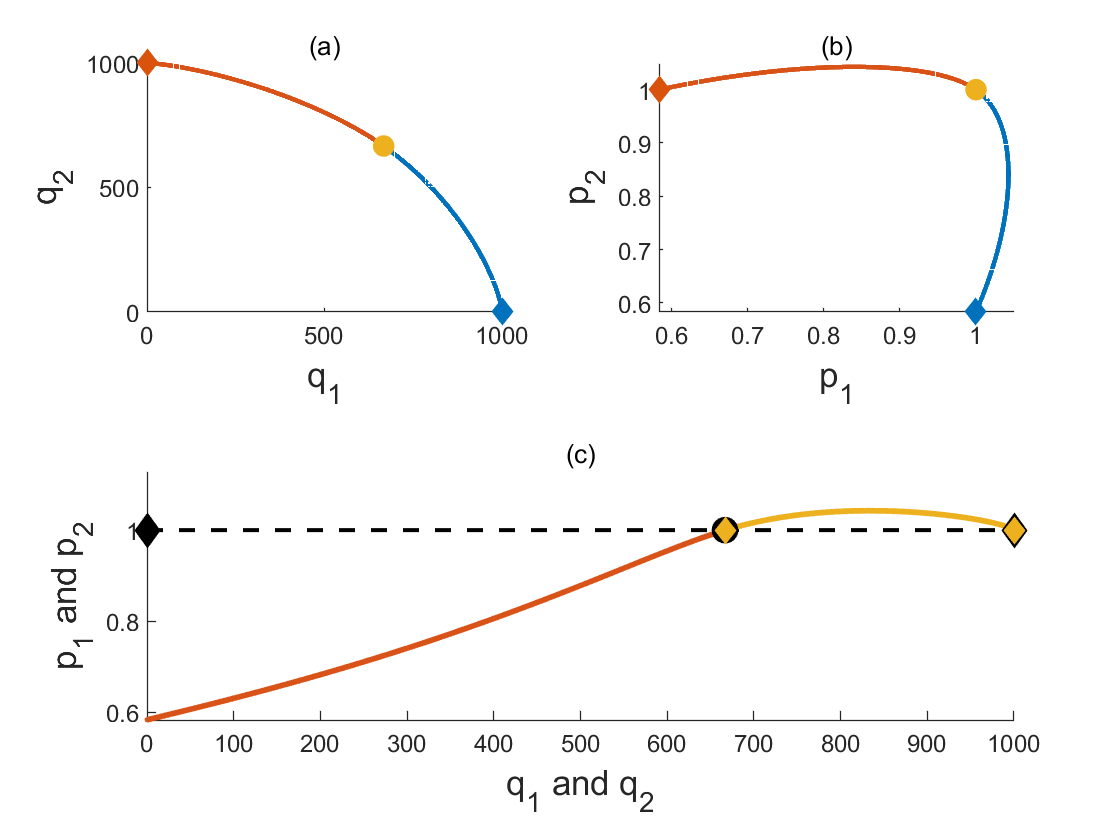

way1 = 'D:/Code/C/level2/work3/fig3_1.bin';
% way1 = 'C:/Users/w3397/Downloads/fig3_1.bin';
way2 = 'D:/Code/C/level2/work3/fig3_2.bin';
way3 = 'D:/Code/C/level2/work3/fig3_3.bin';
way4 = 'D:/Code/C/level2/work3/fig3_4.bin';

fileID1=fopen(way1,'r');
fileID2=fopen(way2,'r');
fileID3=fopen(way3,'r');
fileID4=fopen(way4,'r');


A = fread(fileID1,[5 inf],'double');
B = fread(fileID2,[5 inf],'double');
C = fread(fileID3,[5 inf],'double');
D = fread(fileID4,[5 inf],'double');

fclose(fileID1);
fclose(fileID2);
fclose(fileID3);
fclose(fileID4);
tiledlayout(2,2)
nexttile
title("(a)")
ylabel('q_2',"FontSize",13)
xlabel('q_1',"FontSize",13)
hold on;
plot(D(2,:),D(3,:),'LineWidth',2)
plot(B(2,:),B(3,:),'LineWidth',2)
scatter(666.666,666.666,66,"filled","o")
scatter(1000,0,66,[0 114 189]/255,"filled","d")
scatter(0,1000,66,[217 83 13]/255,"filled","d")
hold off

nexttile
title("(b)")
ylabel('p_2',"FontSize",13)
xlabel('p_1',"FontSize",13)
hold on;
plot(C(4,:),C(5,:),'LineWidth',2)
plot(A(4,:),A(5,:),'LineWidth',2)
scatter(1,1,66,[237 177 32]/255,"filled","o")
scatter(1,7/12,66,[0 114 189]/255,"filled","d")
scatter(7/12,1,66,[217 83 13]/255,"filled","d")
ylim([0.583 1.05])
xlim([0.583 1.05])
hold off


nexttile([1 2])
title("(c)")
ylabel('p_1 and p_2',"FontSize",13)
xlabel('q_1 and q_2',"FontSize",13)
hold on;
plot([0 1000],[1 1],"LineWidth",1.5,"LineStyle","--","Color",[0 0 0])
scatter(B(2,:),B(4,:),3)
scatter(D(2,:),D(4,:),3)
x1 = 5;
scatter(2000/3,1,100,[0 0 0],"filled","o")
scatter(2000/3,1,66,[237 177 32]/255,"filled","d")
scatter(0,1,100,[0 0 0],"filled","d")
scatter(1000,1,100,[0 0 0],"filled","d")
scatter(1000,1,66,[237 177 32]/255,"filled","d")
ylim([0.583 1.13])
hold off